% mVEpre = mVE; mVIpre = mVI;
% f_EnI0 = MeanFieldEst_BkGd(C_EE,C_EI,C_IE,C_II,...
%                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                    lambda_E,S_Elgn,rE_amb,S_amb,...
%                                    lambda_I,S_Ilgn,rI_amb,...
%                                    gL_E,gL_I,Ve,Vi,mVE,mVI);

collect from networks

f_EnI0 = [E_Rate;I_Rate]

函数或变量 'E_Rate' 无法识别。

mVs0 = [nanmean(oVE);nanmean(oVI)]

%% For firing rates from simulation, see mVs from single neurons

f_EnI = zeros(size(f_EnI0)); % from simulation
% simulate one neuron                              
[mVE,f_EnI(1)] = MEanFieldEst_SingleCell('e', f_EnI0, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi);
[mVI,f_EnI(2)] = MEanFieldEst_SingleCell('i', f_EnI0, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi);
loop = loop+1;

mVs = [mVE;mVI]

mVs =     0.4966
    0.6254


f_EnI

f_EnI =     1.6000
    5.8000



f_EnI1 = MeanFieldEst_BkGd(C_EE,C_EI,C_IE,C_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    gL_E,gL_I,Ve,Vi,mVE,mVI)

错误使用  - 
矩阵维度必须一致。

出错 MeanFieldEst_BkGd (line 43)
f_EnI = -(MatEI-eye(2))^-1*(Leak+VecInput);

mVEtest = 0.50:0.005:0.70;
mVItest = 0.50:0.005:0.7;
f_E_MF = zeros(length(mVEtest),length(mVItest));
f_I_MF = zeros(length(mVEtest),length(mVItest));
% collect neuron ind and connectivity for the center HC
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Mean-Field
for mVEInd = 1:length(mVEtest)
    for mVIInd = 1:length(mVItest)
        f_EnI_Now  = MeanFieldEst_BkGd(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    gL_E,gL_I,Ve,Vi,mVEtest(mVEInd),mVItest(mVIInd));
        f_E_MF(mVEInd,mVIInd) = f_EnI_Now(1);
        f_I_MF(mVEInd,mVIInd) = f_EnI_Now(2);
    end                                                         
end

tic
[f_EnI,meanVs,loop] = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                   rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                   gL_E,gL_I,Ve,Vi,...
                                   N_HC,n_E_HC,n_I_HC);
toc

历时 0.344787 秒。


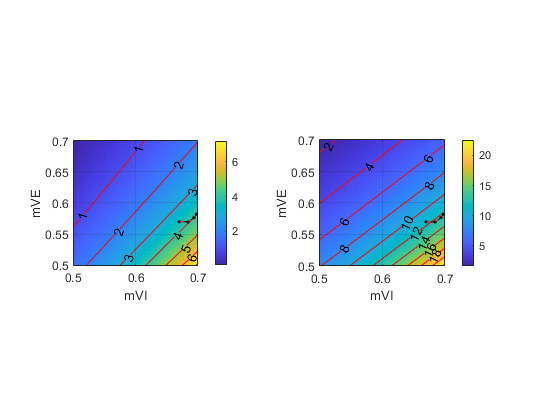


figure(2)
subplot 121
imagesc(mVItest,mVEtest,f_E_MF)
xlabel('mVI'); ylabel('mVE');
set(gca,'YDir','Normal')
colorbar
axis square
hold on
[C1,h1]= contour(mVItest,mVEtest,f_E_MF,'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
axis square
plot_dir (meanVs(2,:)', meanVs(1,:)'); % has to be column vectors
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])

subplot 122
imagesc(mVItest,mVEtest,f_I_MF)
xlabel('mVI'); ylabel('mVE');
set(gca,'YDir','Normal')
colorbar
axis square
hold on
[C2,h2]= contour(mVItest,mVEtest,f_I_MF,'ShowText','on','color','r');
clabel(C2,h2,'FontSize',10,'Color','k')
axis square
plot_dir (meanVs(2,:)', meanVs(1,:)');
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])

tic
[f_EnI,meanVs,loop] = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                   rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                   gL_E,gL_I,Ve,Vi,...
                                   N_HC,n_E_HC,n_I_HC);
toc

历时 0.754809 秒。


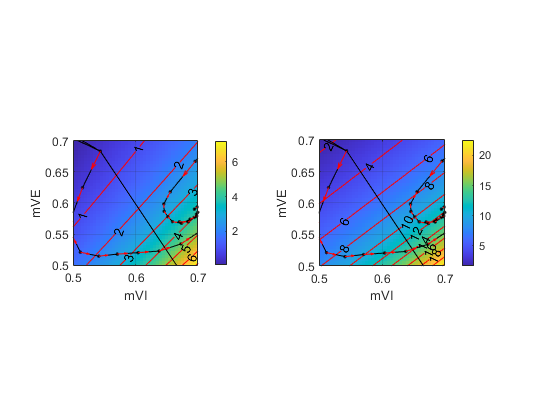

figure(2)
subplot 121
hold on
plot_dir (meanVs(2,:)', meanVs(1,:)'); % has to be column vectors
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])

subplot 122
hold on
plot_dir (meanVs(2,:)', meanVs(1,:)');
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest)])